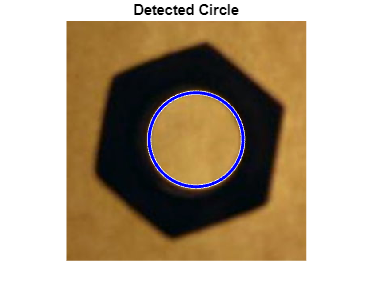

% Read the image
image = imread('HW2.jpg');

% Convert the image to grayscale
grayImage = rgb2gray(image);

% Apply Canny edge detection
edgeImage = edge(grayImage, 'Canny');

% Specify the radius range for circle detection
minRadius = 10;
maxRadius = 100;

% Use the imfindcircles function to detect circles
[centers, radii, ~] = imfindcircles(edgeImage, [minRadius, maxRadius]);

% If you want to find a specific circle, you can choose one based on your criteria
% For example, choose the circle with the largest radius
[~, idx] = max(radii);
x0 = centers(idx, 1);
y0 = centers(idx, 2);
r = radii(idx);

% Display the results
imshow(image);
hold on;
viscircles([x0, y0], r, 'EdgeColor', 'b');
title('Detected Circle');
hold off;

% Read the image and convert to grayscale
clear 
clc

image = imread('HW2.jpg');
image_bw = rgb2gray(image);

img_BW = imbinarize(image_bw); 
img_BW = imcomplement(img_BW); 
edgeImage=edge(img_BW,'canny');
B = bwboundaries(edgeImage,'holes');
B = B{2}; 
% Create an accumulator matrix
[rows, cols] = size(edgeImage);
maxRadius = 80;  % Maximum possible radius
accumulator = zeros(rows, cols, maxRadius);

% Define parameters for circle detection
minRadius = 10;
maxRadius = 100;

% Loop through edge pixels and accumulate votes

edgeRows = B(:,1);
edgeCols = B(:,2);
for r = minRadius:maxRadius
    for theta = 0:0.01:2*pi
        x0 = round(edgeCols - r * cos(theta));
        y0 = round(edgeRows - r * sin(theta));
        
        % Filter out coordinates that are out of bounds
        validIndices = find(x0 >= 1 & x0 <= cols & y0 >= 1 & y0 <= rows);
        
        % Accumulate votes in the accumulator matrix
        indices = sub2ind([rows, cols, maxRadius], y0(validIndices), x0(validIndices), r * ones(size(validIndices)));
        accumulator(indices) = accumulator(indices) + 1;
    end
end

Index exceeds the number of array elements. Index must not exceed 7200000.


% Define a threshold for circle detection
threshold = 100; % Adjust as needed

% Find circles with sufficient votes
[rowsDetected, colsDetected, radiiDetected] = ind2sub(size(accumulator), find(accumulator >= threshold));

% Display the detected circles on the original image
imshow(image);
hold on;

for i = 1:length(rowsDetected)
    x0 = colsDetected(i);
    y0 = rowsDetected(i);
    r = radiiDetected(i);
    viscircles([x0, y0], r, 'EdgeColor', 'b');
end

title('Detected Circles');
hold off;
